clear,clc,close;
%1.数字滤波器的技术指标要求
ap = 1;%通带最大衰减
as = 30;%阻带最小衰减
fp = 200;%通带截止频率
fs = 400;%阻带截止频率
Fs = 1000;%抽样间隔
T = 1/Fs;
 
%2.将数字指标转化成模拟滤波器指标
wp=(2*pi*fp)/Fs;
ws=(2*pi*fs)/Fs;

% 数字指标转模拟指标 预畸变,前面要× (2/T)
wap=2*Fs*tan(wp/2);
was=2*Fs*tan(ws/2);
 
%3.设计模拟滤波器
[N,wac]=buttord(wap,was,ap,as,'s');% N为阶数，wac为3dB截止频率, 's'表示设计的是模拟滤波器
disp("N="+N);

N=3


disp("wac="+wac);

wac=1946.8226


[z,p,k]=buttap(N);% 创建巴特沃斯低通滤波器 z零点p极点k增益
[Bap,Aap]=zp2tf(z,p,k);% 由零极点和增益确定归一化Han(s)系数
[Bbs,Abs]=lp2lp(Bap,Aap,wac);% 低通到低通 计算去归一化Ha(s)
[B,A] = bilinear(Bbs,Abs,Fs); % 模拟域到数字域:双线性不变法
disp("B="+B);

    "B=0.16001"    "B=0.48003"    "B=0.48003"    "B=0.16001"



disp("A="+A);

    "A=1"    "A=-0.049401"    "A=0.33398"    "A=-0.0044933"



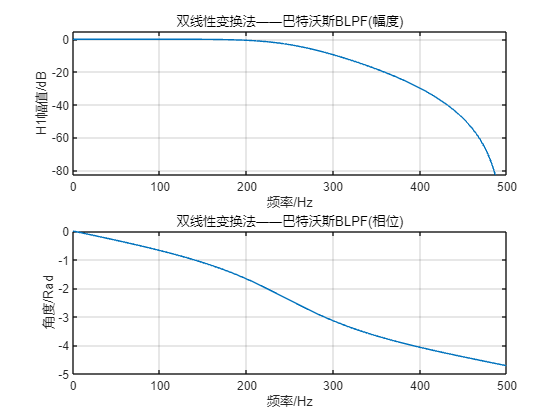

[H1,w] = freqz(B,A);% 根据H(z)求频率响应特性
 
%绘制数字滤波器频响幅度谱
figure(2);
f=w*Fs/(2*pi);
subplot(211);
plot(f,20*log10(abs(H1))); % 绘制幅度响应
grid on;
title('双线性变换法——巴特沃斯BLPF(幅度)');
xlabel('频率/Hz');
axis([0 500 -83 5]);
ylabel('H1幅值/dB');
subplot(212);
plot(f,unwrap(angle(H1)));% 绘制相位响应
grid on;
xlabel('频率/Hz');
ylabel('角度/Rad')
title('双线性变换法——巴特沃斯BLPF(相位)');

wn=[fp,fs]/(Fs/2)

wn =     0.4000    0.8000



[b,a]=butter(3,2*fp/Fs)

b =     0.0985    0.2956    0.2956    0.0985


a =     1.0000   -0.5772    0.4218   -0.0563
